% Finding k and a for a sytem

clc;
s=tf('s');
F=(1.2)/((0.3*s+1)*(s+1)*(1.2*s+1));
for K=4:-0.05:1
    for a=4:-0.05:0.4
         Gs=K*((s+a)^2/s);
         SYS=feedback(F*Gs,1);
         C=stepinfo(SYS);
         C1=C.SettlingTime;
         C2=C.Overshoot;
       
        if C1>0 && C1<2 && C2<10 && C2>2
            p=K;
            q=a;
          
        end
   
    end
       
end
k=p

k = 1.9000

a=q

a = 0.8500

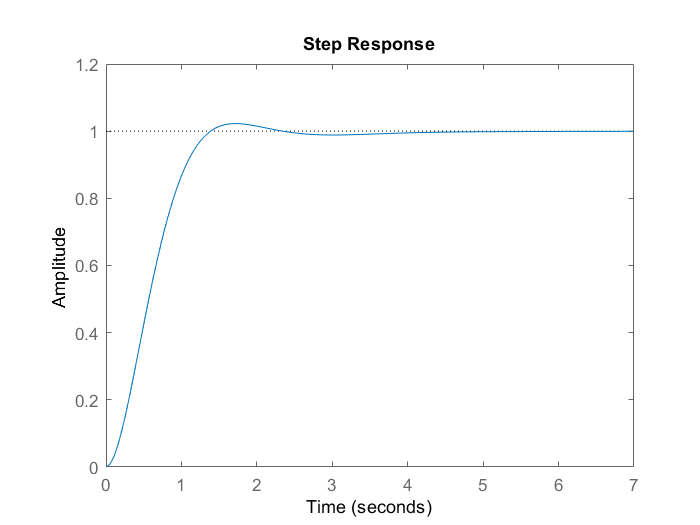

Gs=k*((s+a)^2/s);
SYS=feedback(F*Gs,1);
step(SYS)